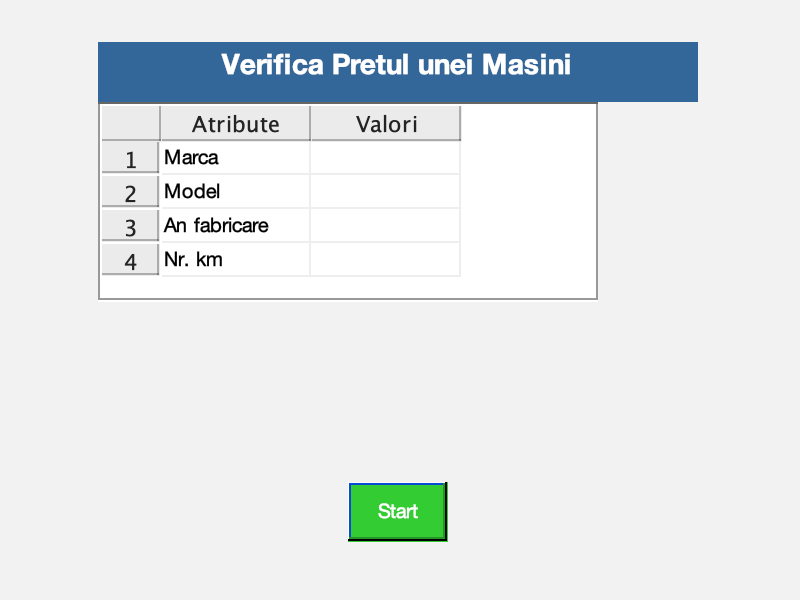

global f1 f2;

f1 = figure('Name', 'Verifica Pretul unei Masini', 'NumberTitle', 'off', 'Position', [100, 100, 400, 300], 'Color', [0.95 0.95 0.95]);

titleText1 = uicontrol('Style', 'text', 'String', 'Verifica Pretul unei Masini', 'FontSize', 14, 'FontWeight', 'bold', 'HorizontalAlignment', 'center', 'Position', [50, 250, 300, 30], 'BackgroundColor', [0.2 0.4 0.6], 'ForegroundColor', [1 1 1]);

data = {'Marca', ''; 'Model', ''; 'An fabricare', ''; 'Nr. km', ''};  
columnNames = {'Atribute', 'Valori'};
t1 = uitable('Parent', f1, 'Data', data, 'ColumnName', columnNames, 'Position', [50, 150, 250, 100], 'BackgroundColor', [1 1 1], 'ForegroundColor', [0 0 0]);  

button1 = uicontrol('Style', 'pushbutton', 'String', 'Start', 'Position', [175, 30, 50, 30], 'Callback', @startButtonCallback1, 'BackgroundColor', [0.2 0.8 0.2], 'ForegroundColor', [1 1 1]);


f2 = [];

set(f1, 'UserData', struct('f1', f1, 'f2', f2));


function startButtonCallback1(~, ~)
    handles = get(gcf, 'UserData');
    close(handles.f1);  % Close the first page
    openSecondPage(handles);
end

function openSecondPage(handles)
    handles.f2 = figure('Name', 'Pret Estimativ:', 'NumberTitle', 'off', 'Position', [500, 100, 400, 300], 'Color', [0.95 0.95 0.95]);

    titleText2 = uicontrol('Style', 'text', 'String', 'Pret Estimativ', 'FontSize', 14, 'FontWeight', 'bold', 'HorizontalAlignment', 'center', 'Position', [50, 230, 300, 30], 'BackgroundColor', [0.2 0.4 0.6], 'ForegroundColor', [1 1 1]);

    currencyButton = uicontrol('Style', 'popupmenu', 'String', {'Euro', 'Lei'}, 'Position', [150, 200, 100, 30], 'Callback', @currencySelectionCallback, 'BackgroundColor', [1 1 1], 'ForegroundColor', [0 0 0]);

    axesMap = axes('Parent', handles.f2, 'Position', [50, 50, 300, 120]);

    verificaButton = uicontrol('Style', 'pushbutton', 'String', 'Verifica alta masina', 'Position', [125, 20, 150, 30], 'Callback', @(src, event) closeSecondPage(src, event, handles), 'BackgroundColor', [0.8 0.2 0.2], 'ForegroundColor', [1 1 1]);

    set(handles.f2, 'UserData', handles);
end

function closeSecondPage(~, ~, handles)
    close(handles.f2);
    openFirstPage(handles);
end

function currencySelectionCallback(hObject, ~)
    selectedCurrency = hObject.String{hObject.Value};
    disp(['Moneda selectata este: ' selectedCurrency]);
end

function openFirstPage(handles)
    f1 = figure('Name', 'Verifica Pretul unei Masini', 'NumberTitle', 'off', 'Position', [100, 100, 400, 300], 'Color', [0.95 0.95 0.95]);

    titleText1 = uicontrol('Style', 'text', 'String', 'Verifica Pretul unei Masini', 'FontSize', 14, 'FontWeight', 'bold', 'HorizontalAlignment', 'center', 'Position', [50, 250, 300, 30], 'BackgroundColor', [0.2 0.4 0.6], 'ForegroundColor', [1 1 1]);

    data = {'Marca', ''; 'Model', ''; 'An fabricare', ''; 'Nr. km', ''};  
    columnNames = {'Atribute', 'Valori'};
    t1 = uitable('Parent', f1, 'Data', data, 'ColumnName', columnNames, 'Position', [50, 150, 250, 100], 'BackgroundColor', [1 1 1], 'ForegroundColor', [0 0 0]); 

    button1 = uicontrol('Style', 'pushbutton', 'String', 'Start', 'Position', [175, 30, 50, 30], 'Callback', @startButtonCallback1, 'BackgroundColor', [0.2 0.8 0.2], 'ForegroundColor', [1 1 1]);

    f2 = [];

    set(f1, 'UserData', struct('f1', f1, 'f2', f2));
end
